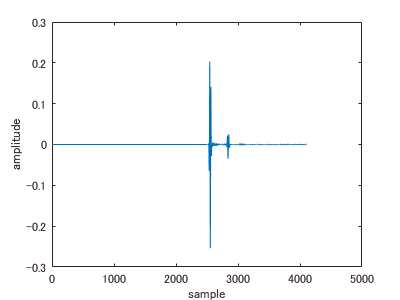

wave = rfdata(:,100,1);
figure;
plot(wave);
xlabel('sample')
ylabel('amplitude')
exportfig('../result/2018_02_20_test_wave_kwave_ring_object','png',[400,300]);

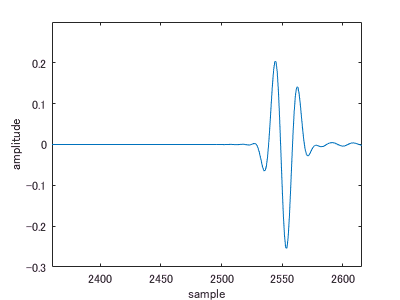

figure;
plot(wave);
xlim([2360 2616])
ylim([-0.300 0.300])
xlabel('sample')
ylabel('amplitude')
exportfig('../result/2018_02_20_test_wave2_kwave_ring_object','png',[400,300]);

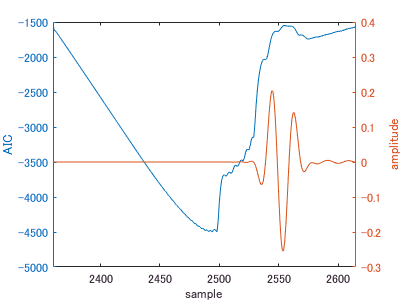

figure;
wave2 = wave(2360:2616);
[AIC] = aicval(wave2);
yyaxis left
plot(2360:2615,AIC);
ylabel('AIC')
xlim([2360 2615])
yyaxis right
plot(2360:2615,wave2(1:end-1))
xlabel('sample')
ylabel('amplitude')
exportfig('../result/2018_02_20_AIC1-1_kwave_ring_object','png',[400,300]);

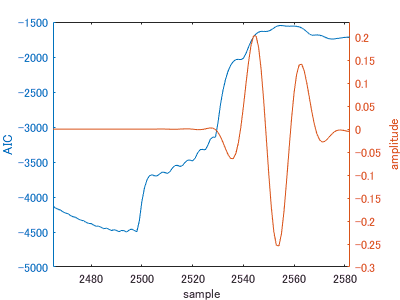

figure;
wave2 = wave(2360:2616);
[AIC] = aicval(wave2);
yyaxis left
plot(2360:2615,AIC);
ylabel('AIC')
xlim([2360 2615])
yyaxis right
plot(2360:2615,wave2(1:end-1))
xlabel('sample')
ylabel('amplitude')
xlim([2465 2582])
ylim([-0.300 0.233])
exportfig('../result/2018_02_20_AIC1-2_kwave_ring_object','png',[400,300]);

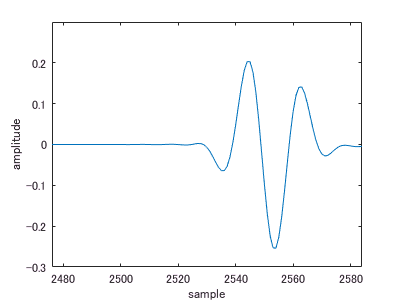

figure;
plot(wave);
xlim([2476 2584])
ylim([-0.300 0.300])
xlabel('sample')
ylabel('amplitude')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\2018_02_20_test2_kwave_ring_object','png',[400,300]);

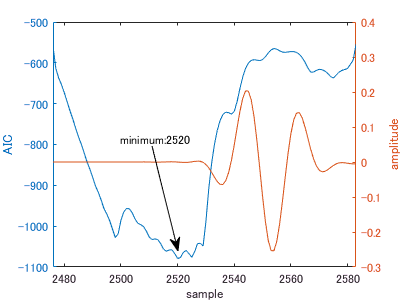

figure;
wave3 = wave(2476:2584);
[AIC2] = aicval(wave3);
yyaxis left
plot(2476:2583,AIC2);
ylabel('AIC')
xlim([2476 2583])
yyaxis right
plot(2476:2583,wave3(1:end-1))
xlabel('sample')
ylabel('amplitude')
annotation('textarrow',[0.38 0.445],[0.5133 0.1633],'String','minimum:2520')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\2018_02_20_AIC2-1_kwave_ring_object_conv','png',[400,300]);

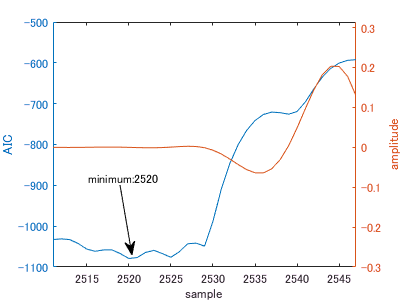



figure;
yyaxis left
plot(2476:2583,AIC2);
ylabel('AIC')
xlim([2476 2583])
yyaxis right
plot(2476:2583,wave3(1:end-1))
xlabel('sample')
ylabel('amplitude')
xlim([2511 2547])
ylim([-0.300 0.314])
annotation('textarrow',[0.3 0.33],[0.3833 0.15],'String','minimum:2520')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\2018_02_20_AIC2-2_kwave_ring_object_conv','png',[400,300]);

上のものは，通常のAIC定義式に則って計算したもの．

下に続くものは，AICをエントロピー（平均情報量）の和としてみなしたときの結果．

・正規分布をモデルとしたエントロピー


$$H_1 \left(x\right)=\frac{1}{2}+\mathrm{log}\left(\sigma \right)+\frac{1}{2}\mathrm{log}\left(2\pi \right)$$


・ラプラス分布をモデルとしたときのエントロピー


$$H_2 \left(x\right)=1+\log \left(\sigma \right)+\frac{1}{2}\log \left(2\right)$$


すなわち


$${\mathrm{AIC}\left(k\right)}_{\mathrm{proposed}} =k\times H_1 \left(X\left\lbrack 1,k\right\rbrack \right)+\left(N-k\right)\times H_2 \left(X\left\lbrack k+1,N\right\rbrack \right)$$


となる．

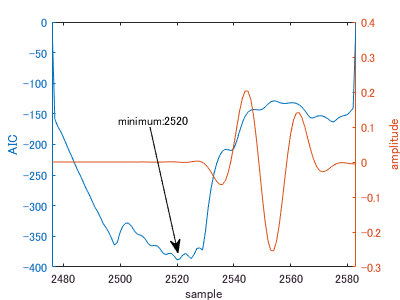

figure;
wave3 = wave(2476:2584);
[AIC3] = proposed_aicval(wave3);
yyaxis left
plot(2476:2583,AIC3);
ylabel('AIC')
xlim([2476 2583])
yyaxis right
plot(2476:2583,wave3(1:end-1))
xlabel('sample')
ylabel('amplitude')
annotation('textarrow',[0.375 0.445],[0.5767 0.1567],'String','minimum:2520')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\2018_02_20_AIC3-1_kwave_ring_object_proposed','png',[400,300]);

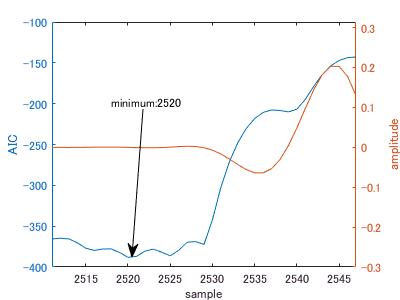


figure;
yyaxis left
plot(2476:2583,AIC3);
ylabel('AIC')
xlim([2476 2583])
yyaxis right
plot(2476:2583,wave3(1:end-1))
xlabel('sample')
ylabel('amplitude')
xlim([2511 2547])
ylim([-0.300 0.314])
annotation('textarrow',[0.3575 0.33],[0.6367 0.1433],'String','minimum:2520')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\AIC2018_02_20_AIC3-2_kwave_ring_object_proposed','png',[400,300]);

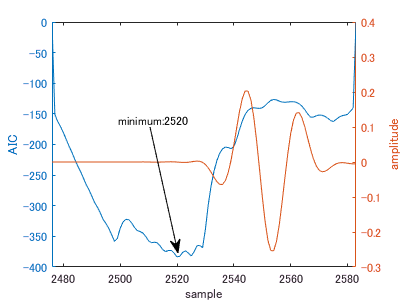

figure;
wave3 = wave(2476:2584);
[AIC4] = norm_dist_aicval(wave3);
yyaxis left
plot(2476:2583,AIC4);
ylabel('AIC')
xlim([2476 2583])
yyaxis right
plot(2476:2583,wave3(1:end-1))
xlabel('sample')
ylabel('amplitude')
annotation('textarrow',[0.375 0.445],[0.5767 0.1567],'String','minimum:2520')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\2018_02_20_AIC4-1_kwave_ring_object_norm_dist','png',[400,300]);

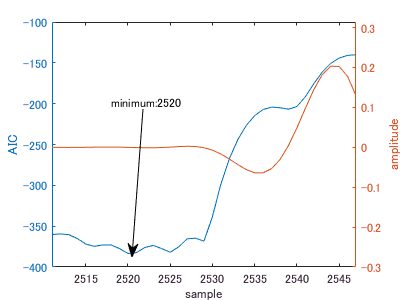


figure;
yyaxis left
plot(2476:2583,AIC4);
ylabel('AIC')
xlim([2476 2583])
yyaxis right
plot(2476:2583,wave3(1:end-1))
xlabel('sample')
ylabel('amplitude')
xlim([2511 2547])
ylim([-0.300 0.314])
annotation('textarrow',[0.3575 0.33],[0.6367 0.1433],'String','minimum:2520')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\AIC2018_02_20_AIC4-2_kwave_ring_object_norm_dist','png',[400,300]);

[a,b] = min(AIC4);

AIC法

　１．従来

　２．提案その１　モデルとする分布を区間ごとに変える．（正規分布・ラプラス分布）

　３．提案その２　モデルとする分布を同じものにする（正規分布）

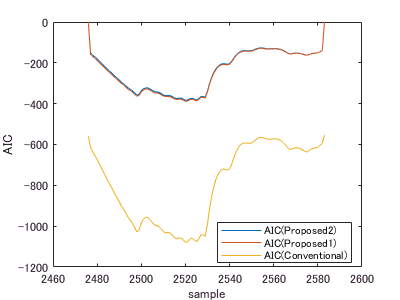

figure;
plot(2476:2583,AIC4,'DisplayName','AIC(Proposed2)');hold on;
plot(2476:2583,AIC3,'DisplayName','AIC(Proposed1)');
plot(2476:2583,AIC2,'DisplayName','AIC(Conventional)');
hold off;
xlabel('sample')
ylabel('AIC')
legend('Location','best')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\AIC\2018_02_20_AIC_normal_distribution\AIC2018_02_20_AIC5_kwave_ring_object_compare','png',[400,300]);

figure;
h1 = histogram(wave3(1:45))

h1 =   Histogram のプロパティ:

             Data: [45×1 double]
           Values: [4 23 14 2 2]
          NumBins: 5
         BinEdges: [-4.0000e-04 -2.0000e-04 0 2.0000e-04 4.0000e-04 6.0000e-04]
         BinWidth: 2.0000e-04
        BinLimits: [-4.0000e-04 6.0000e-04]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を表示


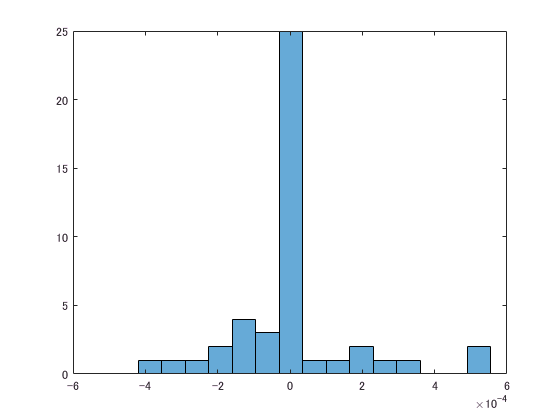

h1.NumBins = 15;

figure;
h2 = histogram(wave3(46:end))

h2 =   Histogram のプロパティ:

             Data: [64×1 double]
           Values: [4 3 33 14 8 2]
          NumBins: 6
         BinEdges: [-0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000]
         BinWidth: 0.1000
        BinLimits: [-0.3000 0.3000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を表示


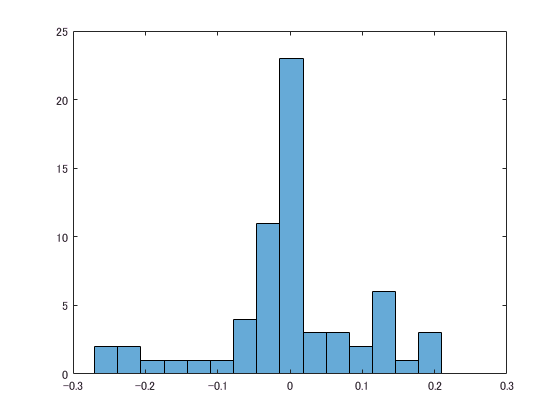

h2.NumBins = 15;

figure;
h3 = histogram(wave3(80:end))

h3 =   Histogram のプロパティ:

             Data: [30×1 double]
           Values: [1 2 17 6 4]
          NumBins: 5
         BinEdges: [-0.3000 -0.2000 -0.1000 0 0.1000 0.2000]
         BinWidth: 0.1000
        BinLimits: [-0.3000 0.2000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を表示


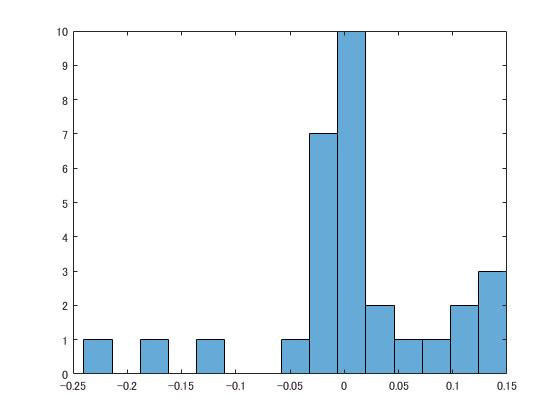

h3.NumBins = 15;

function [a] = aicval(x)
if ~isempty(x)
    n = length(x);
    a = zeros(n-1,1);
    for i=1:n-1
        %compute variance in first part
        s1 = var(x(1:i));
        if s1 <= 0
            s1 = 0;
        else
            s1=log(s1);
        end
        %compute variance in second part
        s2 = var(x(i+1:n));
        if s2 <= 0
            s2 = 0;
        else
            s2=log(s2);
        end
        a(i) = i*(s1) + (n-i+1)*(s2);
    end
else
    a = 0;
end
end

function [a] = proposed_aicval(x)
if ~isempty(x)
    n = length(x);
    a = zeros(n-1,1);
    for i=1:n-1
        %compute variance in first part
        s1 = 1/2 + log(std(x(1:i))) + (1/2)*log(2*pi);
        %compute variance in second part
        s2 =1 + log(std(x(i+1:n))) + (1/2)*log(2);
        a(i) = i*(s1) + (n-i+1)*(s2);
    end
else
    a = 0;
end
a(isinf(a)) = 0;
end

function [a] = norm_dist_aicval(x)
if ~isempty(x)
    n = length(x);
    a = zeros(n-1,1);
    for i=1:n-1
        %compute variance in first part
        s1 = 1/2 + log(std(x(1:i))) + (1/2)*log(2*pi);
        %compute variance in second part
        s2 = 1/2 + log(std(x(i+1:n))) + (1/2)*log(2*pi);
        a(i) = i*(s1) + (n-i+1)*(s2);
    end
else
    a = 0;
end
a(isinf(a)) = 0;
end